# Analysis of Antarctic sectors

There are three sectors available:

- SA := South Africa, 

- WS := Weddell Sea,

-  and EA := East Antarctica

## Table of contents

- Preamble

- Ice concentration (aice)

- Pancake ice concentration

- Pancake ice width

- Pancake ice growth 

- SWH presence

- SWH distance into the ice

- Ice velocities

- Wind velocities 

- Win and ice correlation

- Ice thickness

## 1. Preamble

%% Read in the data.
clear
close all
addpath functions
addpath packages/quiverwcolorbar
%ncdisp(filename)

% Parameters
sector = "SA";
grid = 'gx1';
case_name = '3month';
filedir = 'cases/3month/history/iceh.2005-09-30.nc';
[lat,lon,row] = grid_read(grid);

% Make sector mask
[len,wid] = size(lat);

## 2. Ice area

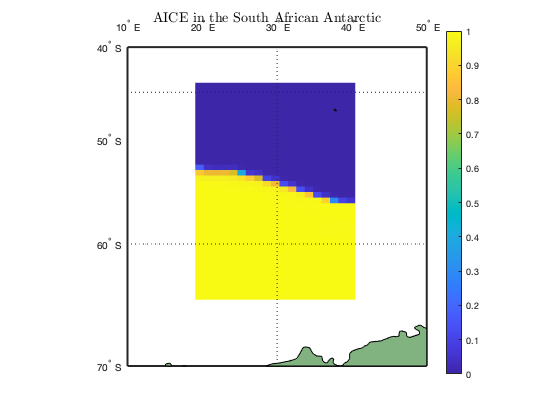

variable = "aice";
sector_data = data_format_sector(filedir,variable,sector);
%data = data(sector_mask);
%color_map = seaicecolormap();
latitude = [-90,-60];
longitude = [10,50];
figure(1)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("AICE in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

## 3. Pancake ice concentration

Floe size categories:

fsd_cats = ncread(filedir,'NFSD');
nfsd = length(fsd_cats);
fprintf('NFSD is: %g', nfsd)

NFSD is: 16

fprintf('The FSD categories are: [');

The FSD categories are: [

fprintf('%g ', fsd_cats);

2.6884 9.79845 21.6721 40.7349 70.1407 113.694 175.577 259.837 369.62 506.24 668.209 850.477 1144.68 1583.1 2147.63 2913.48 

fprintf(']\n');

]


Define floes with radii $< 10$m as pancakes (i.e., the smallest two FSD categories).

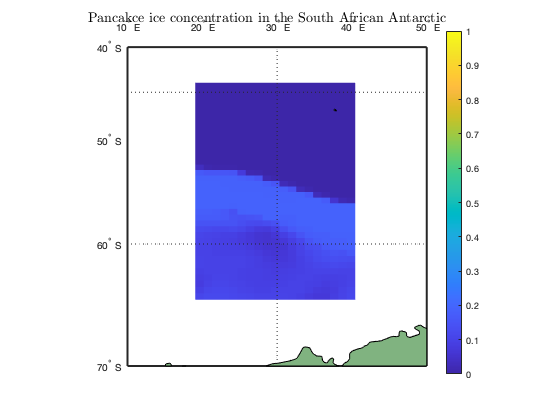

variable = "afsd";
 % Grid
grid = "gx1";
[lat,lon,row] = grid_read(grid);
% Read in data
dim = 3;
data = data_format(filedir,variable,row,lat,lon,dim);
data = data(:,:,1) + data(:,:,2); % Smallest 2 categories combined (ie. pancake)
ocean_mask = data_format(filedir,'tmask',row,lat,lon);
% Coordinates
coords = sector_coords(sector); % (NW;SW,NE,SE) (lat,lon)
for i = 1:4
    [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
end
[len,wid] = size(data);
sector_data = zeros(len,wid);
sector_mask = false(len,wid);
sector_data = ~ocean_mask*NaN;
for i = 0:lat_out(1)-lat_out(2)
    sector_mask(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = true;
    sector_data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3));
end


latitude = [-90,-60];
longitude = [10,50];
figure(3)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("Pancakce ice concentration in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

    %colormap turbo

### 3. a) FSD into the ice pack

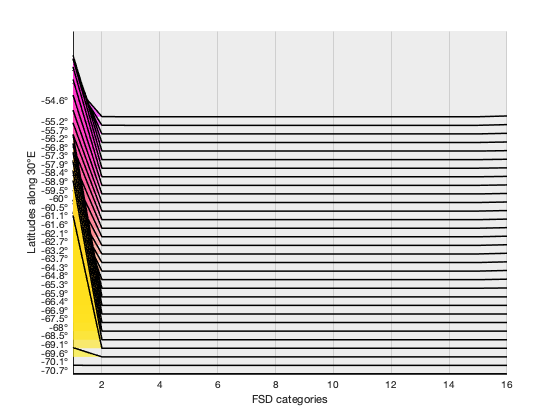


addpath packages/joyPlot
variable = "afsd";
transect_coords = [coords(1,1), (coords(1,2) + coords(3,2))/2];
 % Grid
grid = "gx1";
[lat,lon,row] = grid_read(grid);
% Read in data
dim = 3;
data = data_format(filedir,variable,row,lat,lon,dim);
data_pancake = data(:,:,1) + data(:,:,2); % Smallest 2 categories combined (ie. pancake)
ocean_mask = data_format(filedir,'tmask',row,lat,lon);
% Coordinates
coords = sector_coords(sector); % (NW;NE;SW;SW) (lat,lon)
for i = 1:4
    [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
end
[len,wid] = size(data_pancake);
sector_data = zeros(len,wid);
sector_mask = false(len,wid);
sector_data = ~ocean_mask*NaN;
for i = 0:lat_out(1)-lat_out(2)
    sector_mask(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = true;
    sector_data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = data_pancake(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3));
end

[lat_tran,lon_tran] = lat_lon_finder(transect_coords(1),transect_coords(2),lat,lon);

aice = data_format(filedir,'aice',row,lat,lon);
ice_idx = false(1,lat_tran);
for j = lat_tran:-1:1
    if aice(lon_tran,j)>eps
        ice_idx(j) = true;
    end
end
lat_subset = lat(lon_tran,lat_tran:-1:1);

lat_subset_ice = lat_subset(ice_idx);

for j = lat_tran:-1:1
    if ice_idx(j) == 1
        for i = 1:length(fsd_cats)
            transect_fsd(j,i) = data(lon_tran,j,i);
        end
    end
end

transect_fsd_subset = transect_fsd(ice_idx,:);
transect_fsd_data = transect_fsd_subset;

threshold = 0;
if threshold == 1
    transect_fsd_threshold = false(1,nfsd);
    for i = 1:nfsd
        if sum(transect_fsd(:,i))>0.05
            transect_fsd_threshold(i) = true;
        end
    end
    
    for i = 1:length(lat_subset_ice)
        mean_vec(i) = mean(transect_fsd_subset(i,:));
    end
    transect_fsd_subset_threshold = transect_fsd_subset(:,transect_fsd_threshold);
    transect_fsd_data = transect_fsd_subset_threshold;
end
Ndecimals = 1; 
f = 10.^Ndecimals; 
[len,wid] = size(transect_fsd_data);
figure(31)
joyPlot(transect_fsd_data',1:wid,0.01,'FaceColor','position','FaceAlpha',0.6)
set(gca,'Color',[0.93 0.93 0.93])
set(gca,'XGrid','on')
colormap(spring)
xlabel("FSD categories")
ylabel(['Latitudes along 30' char(176), 'E'])
% Create a char array with alphabet
lat_lbs = round(f.*lat_subset_ice)./f;
n = size(transect_fsd_subset);
% Formatting
ylbls = sprintfc(['%g', char(176)],lat_lbs(n:-1:1));
% Apply
yticklabels(ylbls)

% title("Cell rest")


## 4. Pancake ice width

## 5. Pancake ice growth

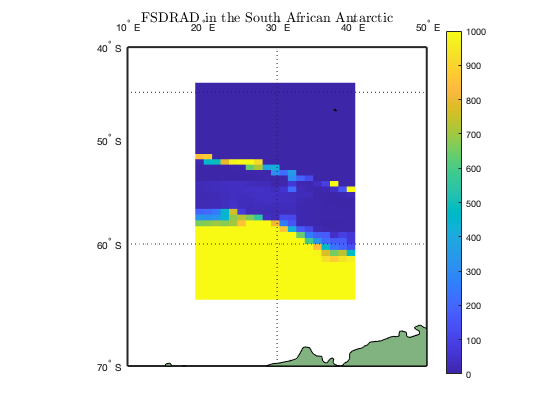

variable = "fsdrad";
sector_data = data_format_sector(filedir,variable,sector);
%data = data(sector_mask);
%color_map = seaicecolormap();
%colormap turbo
latitude = [-90,-60];
longitude = [10,50];
figure(5)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("FSDRAD in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

    %colormap turbo

## 6. SWH presence

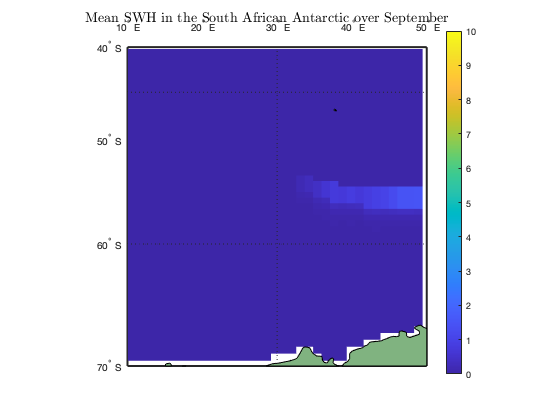

variable = "wave_sig_ht";
day = 1;
month = 9;
year = 2005;
date = sprintf('%d-0%d-0%d', year, month, day);
dim = 2;
datapoints = 24;

for i = 1:datapoints
    % Get the file name
    filename = strcat("cases/",case_name,"/history/iceh.",date,".nc");
    data = data_format(filedir,variable,row,lat,lon,dim); 
    %dx = data_formatted > fsd_max;    
    %swh_miz = data_formatted;
    %swh_miz(idx) = 0.0;
    %idx = swh_miz > wave_height;
    %swh_miz(idx) = 1.0;
    % only print SWH in areas where there is sea ice
    %mask = ice_mask(case_name,date,grid,SIC);
    total_data(:,:,i) = data;
    date = update_date(date);
end
% Proportion of days per season (datapoints)
swh_data = sum(total_data,3)/datapoints;

latitude = [-90,-60];
longitude = [10,50];
figure(6)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("Mean SWH in the ", sector_name(sector), " over September"), 'interpreter','latex','FontSize', 14)

    %colormap turbo

## 7. SWH distance into the ice

## 8. Ice velocities

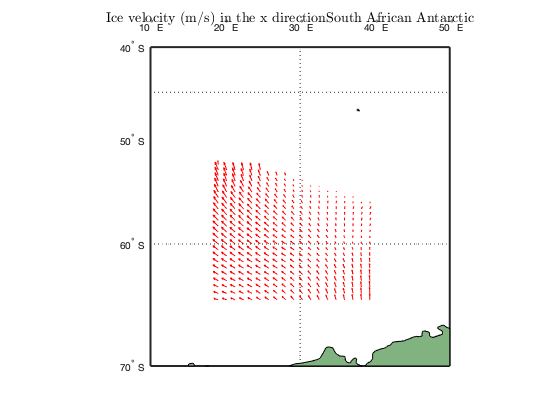

%% ICE velocities
variable = "uvel"; % ice velocity (x)
ice_data_x_raw = data_format_sector(filedir,variable,sector);
variable = "vvel"; % ice velocity (x)
ice_data_y_raw = data_format_sector(filedir,"vvel",sector);
lat0 = lat(sector_mask);
lon0 = lon(sector_mask);
ice_data_x = ice_data_x_raw(sector_mask);
ice_data_y = ice_data_y_raw(sector_mask);

latitude = [-90,-60];
longitude = [10,50];

deltalat_ice = ice_data_x;
deltalon_ice = ice_data_y;
scale = 1; 

figure(8)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    quiverm(lat0,lon0,deltalat_ice,deltalon_ice,'r')
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5]);
    title(strcat("Ice velocity (m/s) in the x direction", sector_name(sector)), 'interpreter','latex','FontSize', 14)



lat_min = lat_lon_finder(coords(2,1),coords(2,2),lat,lon);    
lat_range = lat(lon_tran,lat_tran:-1:lat_min);

[wid,len] = size(lat);
ice_vec_x = reshape(ice_data_x,1,[]);
ice_vec_y = reshape(ice_data_y,1,[]);
lat1 = reshape(lat0,1,[]);
lon1 = reshape(lon0,1,[]);
deltalat_ice_vec = reshape(deltalat_ice,1,[]);
deltalon_ice_vec = reshape(deltalon_ice,1,[]);
mag_ice = sqrt(deltalat_ice_vec.^2+deltalon_ice_vec.^2);
scale = 2;
figure(80)
quiverwcolorbar(lon1',-lat1',deltalon_ice_vec',-deltalat_ice_vec',scale,'bounds',[min(mag_ice) max(mag_ice)]);

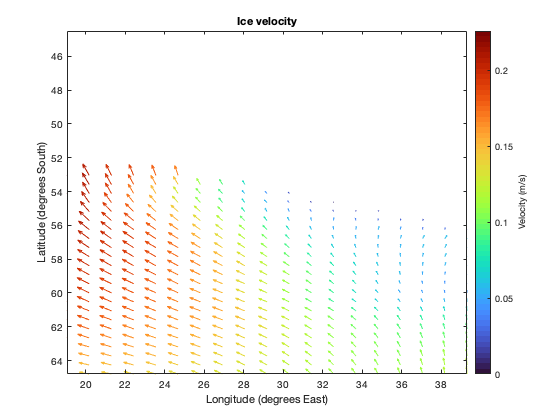

    a = colorbar;
    a.Label.String = 'Velocity (m/s)';
    title('Ice velocity')
    xlabel('Longitude (degrees East)');
    ylabel('Latitude (degrees South)');

"The speed reached $\approx 0.75$$m/s$ , which is the highest ice speed ever recorded in the Southern Ocean to our knowledge" Alberello et al. (2020) *Drift of pancake ice*.

## 9. Wind velocity

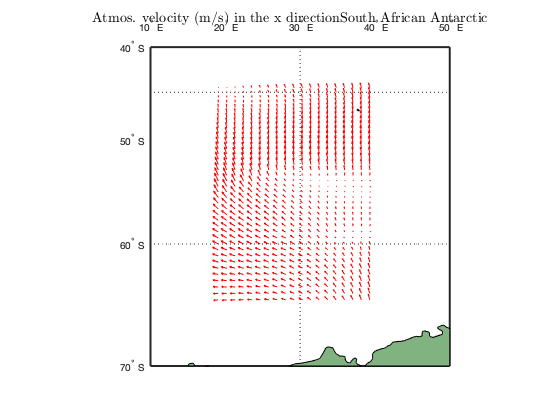

%% ATM velocities
variable = "uatm"; % atm velocity (x)
atm_data_x = data_format_sector(filedir,variable,sector);
atm_data_y = data_format_sector(filedir,"vatm",sector);
lat0 = lat(sector_mask);
lon0 = lon(sector_mask);
atm_data_x = atm_data_x(sector_mask);
atm_data_y = atm_data_y(sector_mask);

latitude = [-90,-60];
longitude = [10,50];

deltalat_atm = atm_data_x;
deltalon_atm = atm_data_y;


figure(9)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    quiverm(lat0,lon0,deltalat_atm,deltalon_atm,'r')
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5]);
    %a = colorbar;
    %a.Label.String = 'Velocity (m/s)';
    title(strcat("Atmos. velocity (m/s) in the x direction", sector_name(sector)), 'interpreter','latex','FontSize', 14)


lat_min = lat_lon_finder(coords(2,1),coords(2,2),lat,lon);    
lat_range = lat(lon_tran,lat_tran:-1:lat_min);

[wid,len] = size(lat);
atm_vec_x = reshape(atm_data_x,1,[]);
atm_vec_y = reshape(atm_data_y,1,[]);
lat1 = reshape(lat0,1,[]);
lon1 = reshape(lon0,1,[]);

deltalat_atm_vec = reshape(deltalat_atm,1,[]);
deltalon_atm_vec = reshape(deltalon_atm,1,[]);
mag_atm = sqrt(deltalat_atm_vec.^2+deltalon_atm_vec.^2);
scale = 0.3;
figure(90)
quiverwcolorbar(lon1',-lat1',deltalon_atm_vec',-deltalat_atm_vec',scale,'bounds',[min(mag_atm) max(mag_atm)]);

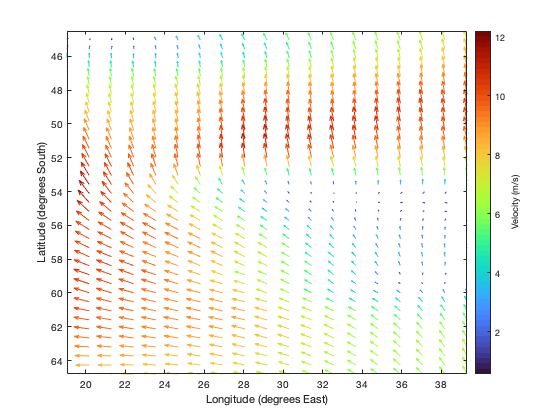

    a = colorbar;
    a.Label.String = 'Velocity (m/s)';
    xlabel('Longitude (degrees East)');
    ylabel('Latitude (degrees South)');

## 10. Wind and ice velocity correlaion

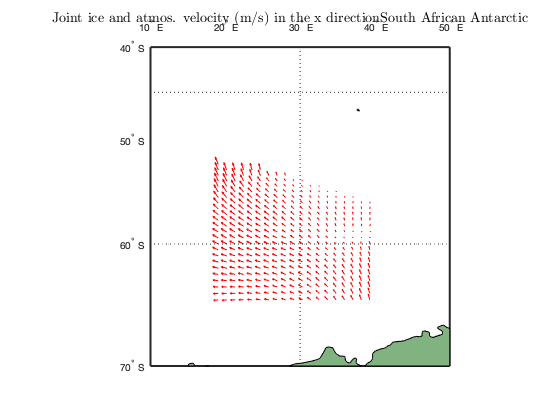

ice_lat_mask = deltalat_ice>eps;
ice_lon_mask = deltalon_ice>eps;
% Apply ice mask, so we only take wind data where there is ice
deltalat_atm_mask = deltalat_atm.*ice_lat_mask;
deltalon_atm_mask = deltalon_atm.*ice_lat_mask;
% Do we need this?
atm_vec = [deltalat_atm_mask, deltalon_atm_mask]; %(lat,lon)
ice_vec = [deltalat_ice, deltalon_ice]; %(lat,lon)
%% How far the did winds move the ice?
% Project ice onto atmosphere
proj = dot(ice_vec,atm_vec)/dot(atm_vec,atm_vec)*atm_vec;


%deltalat_corr = deltalat_atm.*ice_lat_mask + deltalat_ice;
%deltalon_corr = deltalon_atm.*ice_lon_mask + deltalon_ice;

figure(10)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    quiverm(lat0,lon0,proj(:,1),proj(:,2),'r')
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5]);
    %a = colorbar;
    %a.Label.String = 'Velocity (m/s)';
    title(strcat("Joint ice and atmos. velocity (m/s) in the x direction", sector_name(sector)), 'interpreter','latex','FontSize', 14)


%% What influence does wind have on the ice velocity?    
[len, ~] = size(proj);    
for i = 1:len
    mag_proj(i) = sqrt(proj(i,1)^2+proj(i,2)^2);
end
scale = 2;
figure(99)
quiverwcolorbar(lon1',-lat1',proj(:,2),-proj(:,1),scale,'bounds',[min(mag_proj) max(mag_proj)]);

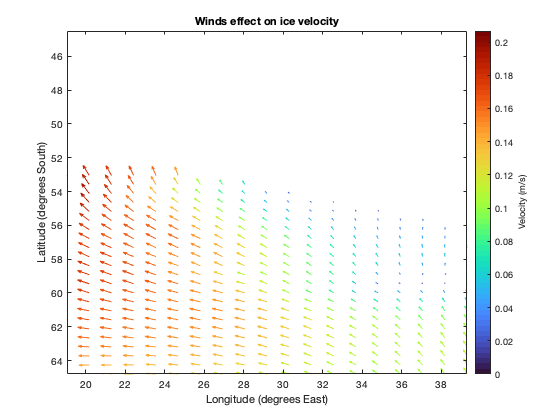

    a = colorbar;
    a.Label.String = 'Velocity (m/s)';
    title('Winds effect on ice velocity')
    xlabel('Longitude (degrees East)');
    ylabel('Latitude (degrees South)');


% Calculate percentage ice velocity is of wind velocity in that direction
cos(proj,atm_vec)
for i = 1:length(proj)
    norm_proj(i,:) = proj(i,:)/norm(proj(i,:));
end


## 11. Ice thickness

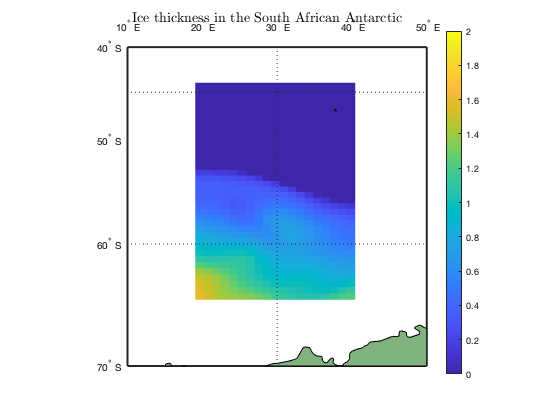

variable = "hi";
sector_data = data_format_sector(filedir,variable,sector);
%data = data(sector_mask);
%color_map = seaicecolormap();
%colormap turbo
latitude = [-90,-60];
longitude = [10,50];
figure(11)
w = worldmap('world');
    axesm miller; %, eqaazim eqdazim vperspec, eqdazim flips the x-axis, and y-axis to eqaazim. cassini
    setm(w, 'Origin', [0 0 0]);
    setm(w, 'maplatlimit', [-70,-40]);
    setm(w, 'maplonlimit', [10,50]);
    setm(w, 'meridianlabel', 'on')
    setm(w, 'parallellabel', 'on')
    setm(w, 'mlabellocation', 10);
    setm(w, 'plabellocation', 10);
    setm(w, 'mlabelparallel', 0);
    setm(w, 'grid', 'on');
    setm(w, 'frame', 'on');
    setm(w, 'labelrotation', 'on')
    pcolorm(lat,lon,sector_data)
    land = shaperead('landareas', 'UseGeoCoords', true);
    geoshow(w, land, 'FaceColor', [0.5 0.7 0.5])
    colorbar
    caxis(colorlims(variable));
    title(strcat("Ice thickness in the ", sector_name(sector)), 'interpreter','latex','FontSize', 14)

    %colormap turbo

## Functions

function coords = sector_coords(sector)
% Coordinates of sector
%   There are three sectors available:
%       SA := South Africa, 
%       WS := Weddell Sea,
%       and EA := East Antarctica
    if sector == "SA"
        coords = [-45,20;-65,20;-45,40;-65,40]; %(NW;SW,NE,SE)
    elseif sector == "EA"
        coords = [];
    elseif sector == "WS"
        coords = [];
    end
end

function sector_data = data_format_sector(filedir,variable,sector,dim)
     if ~exist('dim', 'var')
        dim = 2; 
     end

    % Grid
    grid = "gx1";
    [lat,lon,row] = grid_read(grid);
    % Read in data
    data = data_format(filedir,variable,row,lat,lon,dim);
    ocean_mask = data_format(filedir,'tmask',row,lat,lon);
    % Coordinates
    coords = sector_coords(sector); % (NW;NE;SW;SW) (lat,lon)
    for i = 1:4
        [lat_out(i),lon_out(i)] = lat_lon_finder(coords(i,1),coords(i,2),lat,lon);
    end
    [len,wid] = size(data);
    sector_data = zeros(len,wid);
    sector_mask = false(len,wid);
    sector_data = ~ocean_mask*NaN;
    for i = 0:lat_out(1)-lat_out(2)
        sector_mask(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = true;
        sector_data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3)) = data(lon_out(1):lon_out(3), lat_out(1)-i:lat_out(3));
    end
    
end

function name = sector_name(sector)
    if sector == "SA"
        name = "South African Antarctic";
    elseif sector == "WS"
        name = "Weddell Sea";
    elseif sector == "EA"
        name = "East Antarctic";
    else
        name = "";
        
    end
end
